clear; clc; close all

Load a test image

impath = "C:\Users\Iñigo\OneDrive - Mondragon Unibertsitatea\BIOMEDIKA\MASTER\2nd Semester\ADV_IM_PROCESSING\PARKINSON_DRAWINGS\spiral\training\healthy"

impath = "C:\Users\Iñigo\OneDrive - Mondragon Unibertsitatea\BIOMEDIKA\MASTER\2nd Semester\ADV_IM_PROCESSING\PARKINSON_DRAWINGS\spiral\training\healthy"

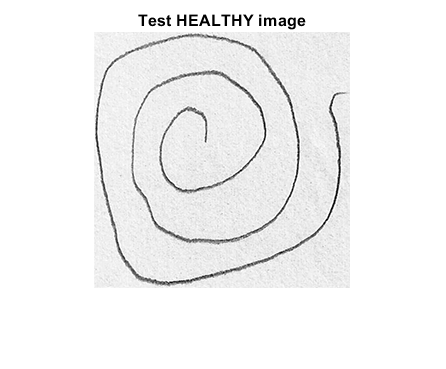

im = im2double(rgb2gray(imread(impath + "\V01HE02.png")));
imshow(im, []); title('Test HEALTHY image')

[M,N] = size(im);

View image histogram

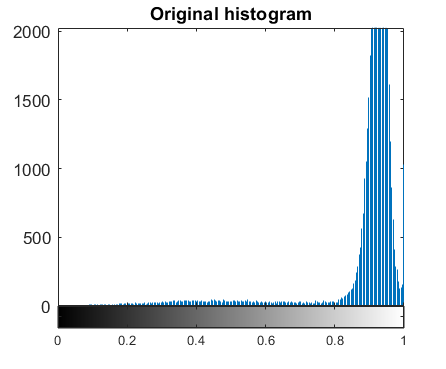

imhist(im);
title('Original histogram');

Apply Otsu's method thresholding to get the ROI of the stroke. Isolate the stroke.

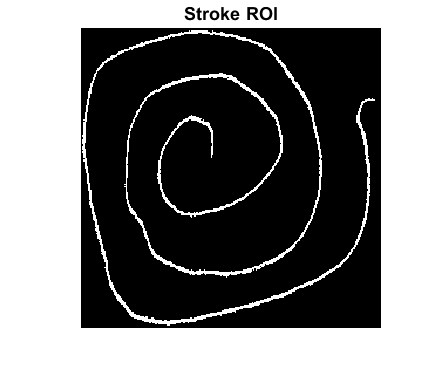

T = graythresh(im);
ROI = im < T;
imshow(ROI); title('Stroke ROI')

Get the skeleton of the image and prune it

skel_im = bwmorph(ROI, 'skel', Inf);
subplot(121);imshow(skel_im); title('Skeleton of ROI')
pruned_skel_im = bwmorph(skel_im, 'spur', 3);
subplot(122);imshow(pruned_skel_im); title('Pruned skeleton')

Start a region growing procedure storing the positions of each step. Get a starting position

% First we need to get one of the starting points. Hit or miss. No matter
% which one we take and the order of growing, because we will look at the
% spectral information of the signal.
pattern = [0,0,0; 1, 1, 0; 0, 0, 0];
hits = myhitnmiss(pruned_skel_im, pattern, 8);
[Y_init, X_init] = find(hits, 1);
target_im = zeros(M,N); target_im(Y_init, X_init) = 1;
dilater = strel('square', 3);

Start region growing.

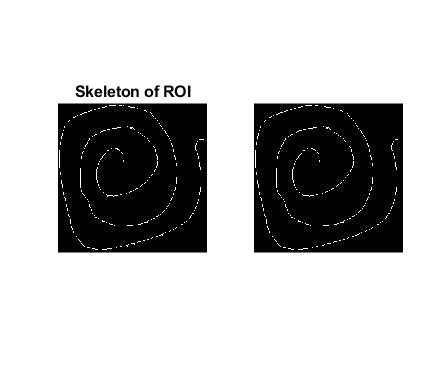

Xk = target_im;
i = 1;
canv = pruned_skel_im;

while (1)
    dil_point = imdilate(Xk, dilater);
    both_im = canv & dil_point;
    new_point = xor(Xk, both_im);
    canv = canv - both_im;
    imshow(canv); pause(0.001)
    Xk = new_point;
    if isequal(find(new_point == 1, 1))
        break;
    else
        [Y_pts(i), X_pts(i)] = find(new_point, 1); 
    end
    i = i + 1;
end